# Aero 2: 2 DOF PD Control

## FOR DETAILS OF THIS LAB, SEE 6_TEACHING/1_CONTROLS/AERO2/ADVANCED

## PD Control Design

### Control Specifications

Design PD gains according to the following set of specifications:

- Peak time: $t_p \le 2.5 $ s for pitch angle and $t_p \le 3.5$ s for yaw angle.

- Percent Overshoot: $PO \le 5\%$ for both axes.

Find the second-order time-domain design requirements based on the desired peak time and overshoot specifications.

Pitch Axis

% Peak time and overshoot specifications
PO_p = 5;
tp_p = 2.5;
% Damping ratio from overshoot specification.
zeta_p = -log(PO_p/100) * sqrt( 1 / ( ( log(PO_p/100) )^2 + pi^2 ) );
% Natural frequency from specifications (rad/s)
wn_p = pi / ( tp_p * sqrt(1-zeta_p^2) );

Yaw Axis

% Peak time and overshoot specifications
PO_y = 5;
tp_y = 3.5;
% Damping ratio from overshoot specification.
zeta_y = -log(PO_y/100) * sqrt( 1 / ( ( log(PO_y/100) )^2 + pi^2 ) );
% Natural frequency from specifications (rad/s)
wn_y = pi / ( tp_y * sqrt(1-zeta_y^2) );

### Find PD Gains

Load the AERO 2 Parameters

aero2_parameters;

Load stiffness, damping, and thrust parameters values.

aero2_parameters_id;

Find the PD gains for pitch axis based on equations 4 and 5 

% Pitch proportional gain (V/rad)
kp_p = (Jp*wn_p^2-Ksp)/Kpp/Dt

kp_p = 116.2420

% Pitch Derivative gain (V-s/rad)
kd_p = (2*zeta_p*wn_p*Jp-Dp)/Kpp/Dt

kd_p = 99.6990

Find the PD gains for the yaw using equations 6 and 7.

% Yaw proportional gain (V/rad)
kp_y = Jy*wn_y^2/Kyy/Dt

kp_y = 35.8626

kd_y = 38.0289

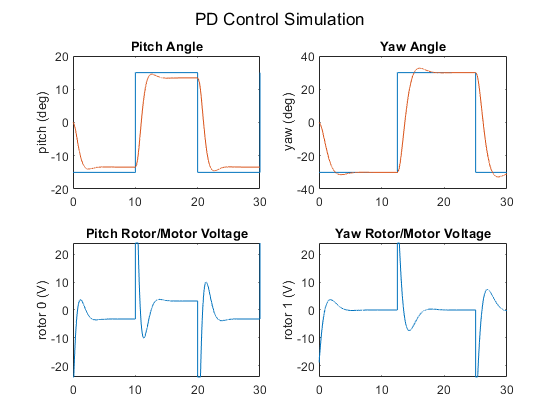

% Yaw derivative gain (V-s/rad)
kd_y = (2*zeta_y*wn_y*Jy-Dy)/Kyy/Dt

## Running the PD Control on the Hardware

The `q_aero2_2dof_pd `Simulink model shown in Figure 4 will be used with QUARC to run the PD control on the Aero 2.

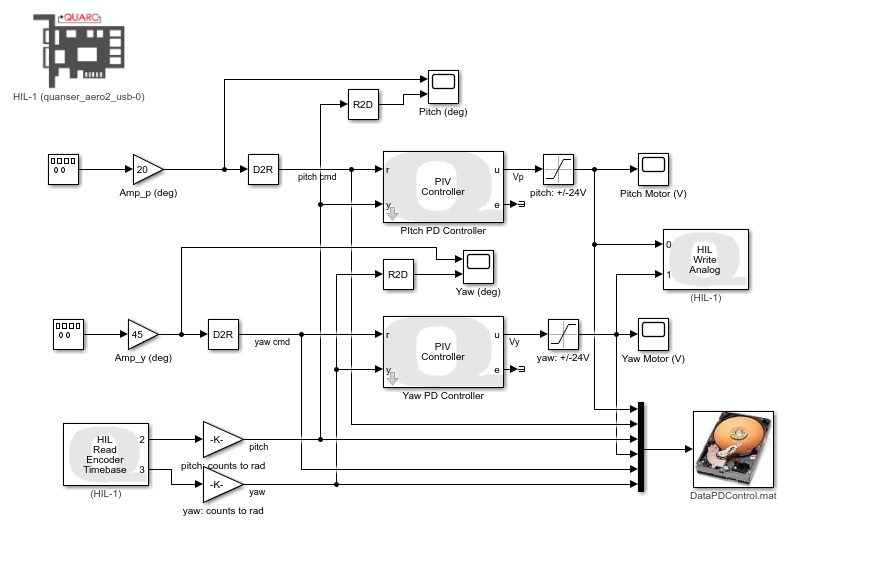

Figure 4: Simulink model used with QUARC to run the PD control on the Aero 2.

The Simulink model uses the `HIL Write Analog `and `HIL Read Timebase `blocks from the *QUARC Targets *library to apply the control input voltage to the rotors and measure the corresponding pitch and yaw response. The response is saved into a MATLAB *.mat files using the `To Host File `block. The PD control on each axis is implemented using the QUARC *PIV Controller *block.

### Aero 2 Setup

- Make sure the Aero 2 has been tested as instructed in the Quick Start Guide. 

- Launch MATLAB and browse to the working directory that includes the Simulink models for this lab.

- Configure the Aero 2 in the Half-Quadrotor configuration: 

- **Unlock** the pitch axis and **unlock **the yaw axis.

- Rear rotor 1 is **vertical **and front rotor 0 is **horizontal**.

- Mount weight on each rotor.

- Connect the USB cable to your PC/laptop.

- Connect the power and turn the power switch ON. The Aero base LED should be red.

Build and run the following Simulink model in QUARC by clicking on the *Monitor & Tune* button.

open("q_aero2_2dof_pd.slx");

The scopes in Figure 5 show a sample pitch angle PD response.

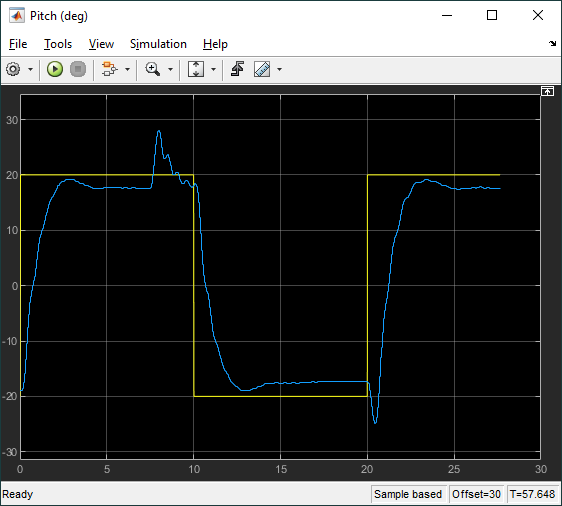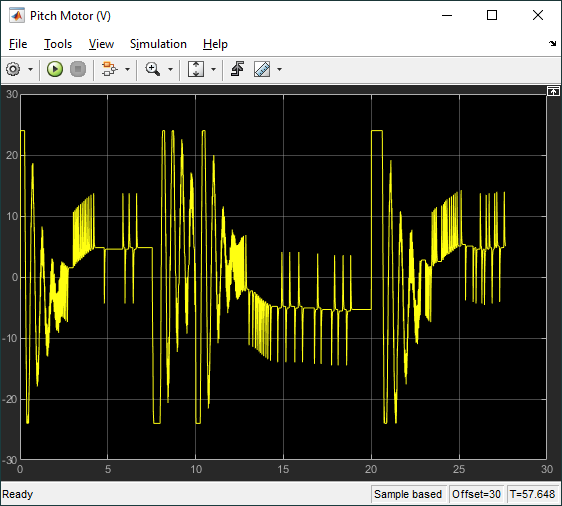

Figure 5 - Pitch PD control response

The scopes in Figure 6 show a sample yaw PD response.

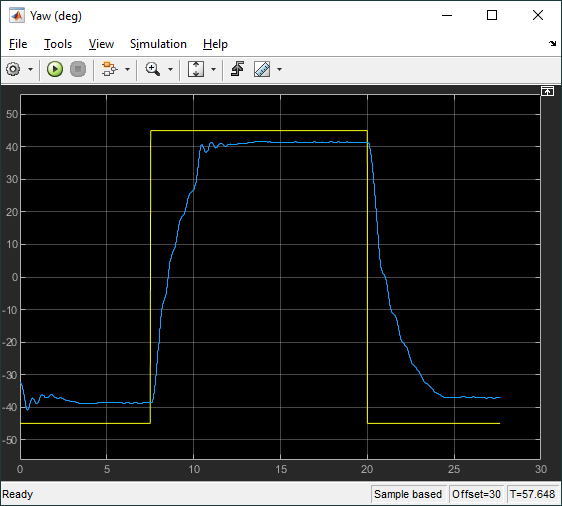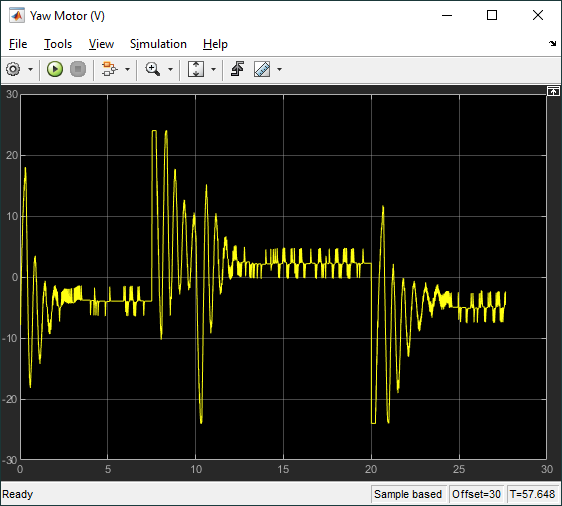

Figure 6 - Yaw PD control response.

Plot Response

% Load measured data from past run
load('DataPDControl.mat');
% store in variables
t = DataPDControl(1,:); % time (s)
Vp = DataPDControl(2,:); % pitch voltage (V)
theta_d = DataPDControl(3,:); % desired pitch angle (rad)
theta = DataPDControl(4,:); % pitch angle (rad)
Vy = DataPDControl(5,:); % yaw voltage (V)
yaw_d = DataPDControl(6,:); % desired yaw angle (rad)
yaw = DataPDControl(7,:); % yaw angle (rad)
%
figure;
subplot(2,2,1);
plot(t,theta_d,t,theta);
title('Pitch');
ylabel('Angle (rad)');
subplot(2,2,3);
plot(t,Vp);
ylabel('Pitch Motor (V)');
xlabel('time (s)');
% 
subplot(2,2,2);
plot(t,yaw_d,t,yaw);
title('Yaw');
ylabel('Angle (rad)');
subplot(2,2,4);
plot(t,Vy);
ylabel('Yaw Motor (V)');
xlabel('time (s)');
sgtitle('PD Control Hardware Response')

Looking at the pitch response when the step starts at 50 s, the peak time and overshoot are approximately:$t_p = 3.41$ s and $PO = \frac{19.3-17.6}{40}\times100=4.30\%$.

Based on the yaw response when the step start at 37.5 s, the peak time and overshoot are approximately:$t_p = 3.50$ s and $PO = 0$

These measurements are taken on step responses that have minimal cross-coupling effect. Comparing these to the control requirements, the peak time of the pitch is slower than anticipated but all the other requirements are met. The pitch peak time could be further reduced by increasing the proportional gain but that may increase the overshoot over 5%. 